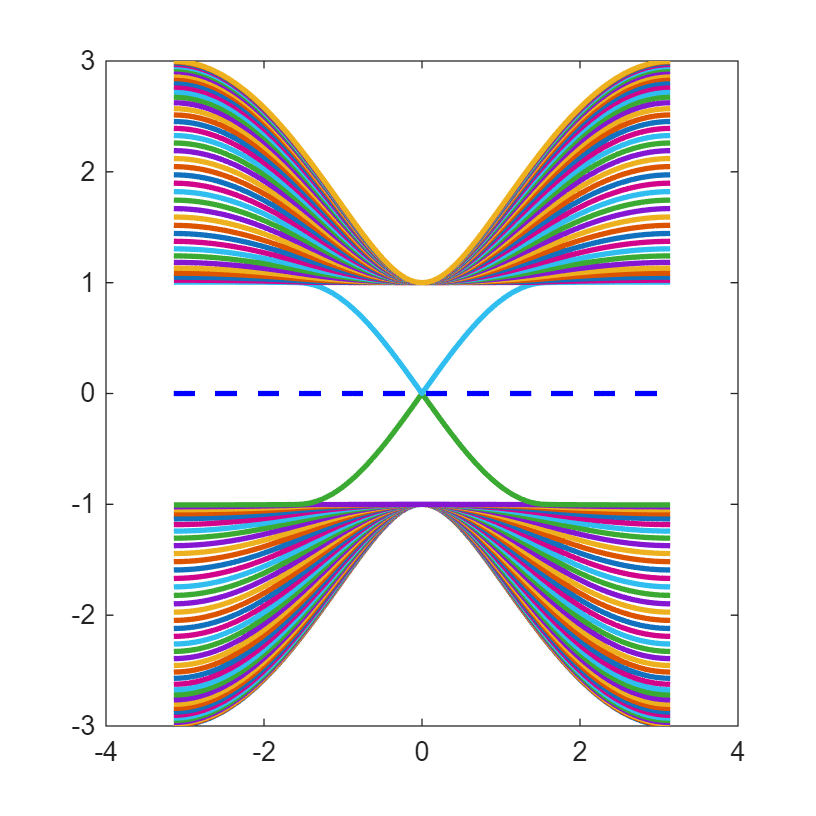

clear;
epsilon = 0;
m = 1.0;
Lx = 2000;
Ly = 40;
Sx = [0, 1; 1, 0];
Sy = [0,-1i;1i,0];
Sz = [1, 0; 0,-1];
H_CC = 0.5 * (kron(diag(ones(1, Ly-1),-1),(1i*Sy)-Sz) + kron(diag(ones(1, Ly-1),-1),(1i*Sy)-Sz)') + (2-m) * kron(eye(Ly),Sz);
V_CC = -0.5 * 1i * kron(eye(Ly),Sx-(1i*Sz));
W = 0;

%% Spectrum
N = 101;
kx = linspace(-pi,pi,N);
Eigen = zeros(size(H_CC,1), N);
for ii = 1:N
    Eigen(:,ii) = eig(H_CC + exp(1i * kx(ii)) * V_CC + exp(-1i * kx(ii)) * V_CC');
end
plot(kx, Eigen, kx, epsilon * ones(1, length(kx)),'b--','LineWidth',2)


R = eye(size(H_CC,1));
R_Spectrum = zeros(size(H_CC,1), Lx);
for ii = 1:Lx
    if ii > 1
        T = Transfer_Matrix(H_CC, V_CC, epsilon, W)*Q;
    else
        T = Transfer_Matrix(H_CC, V_CC, epsilon, W);
    end
    [Q, R] = qr(T);
    [R_diag, ind] = sort(diag(R), 'descend','ComparisonMethod','abs');
    Q = Q(:, ind);
    R_Spectrum(:, ii) = abs(R_diag);
end






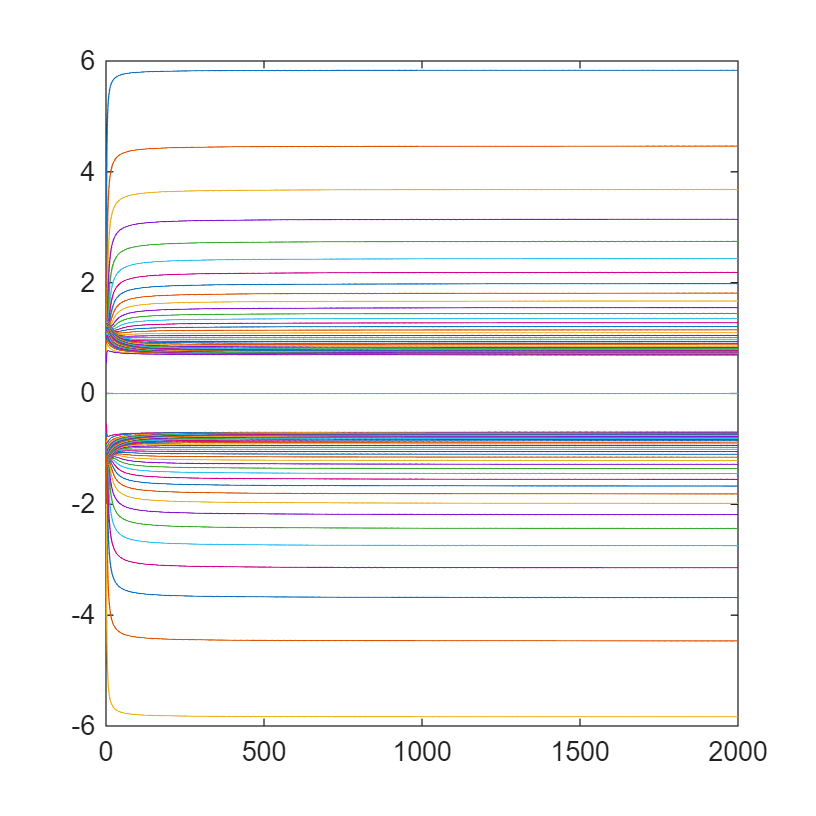

lnR = log(R_Spectrum);
plot(1:Lx, cumsum(lnR,2)./(1:Lx))


Lyapunov_Spectrum = sum(lnR,2)/Lx;  
disp(['Lyapunov Exponent:',num2str(min(abs(Lyapunov_Spectrum)))])

Lyapunov Exponent:5.538e-06


disp(['Localization:',num2str(1./min(abs(Lyapunov_Spectrum)))])

Localization:180571.2978



% ylim([-5,5])
function T = Transfer_Matrix(H_CC, V_CC, FermiEnergy, Disorder)
eta = 1e-5;
[V, Xi, W] = svd(V_CC);
r = rank(Xi);
V = V(:, 1:r);
W = W(:, 1:r);
Xi = Xi(1:r, 1:r);
H_imp = Disorder * diag(rand(1,size(H_CC,1))-0.5);
G = inv((FermiEnergy + 1i * eta) * eye(size(H_CC,1)) - H_CC - H_imp);
G_vv = (V' * G * V) * Xi;
G_ww = (W' * G * W) * Xi;
G_vw = (W' * G * V) * Xi;
G_wv = (V' * G * W) * Xi;

theta = angle(det(G_vw));


T = [inv(G_vw), -inv(G_vw) * G_ww; 
    G_vv * inv(G_vw), G_wv - G_vv * inv(G_vw) * G_ww];
T = exp(1i * theta / r) * T;
end





# 测试用例

% clear;
% Nk = 401;
% ky = linspace(-pi,pi,Nk);
% V_CC = zeros(3);
% V_CC(1,3) = 1;
% Ne = 2*Nk;
% epsilon = linspace(-4,4,Ne);
% [ky_mesh, e_mesh] = meshgrid(ky, epsilon);
% Delta = zeros(Ne, Nk);
% for ii = 1:length(ky)
%     H_CC = [2 * cos(ky(ii)-2*pi/3), 1, 0;
%             1, 2 * cos(ky(ii)+2*pi/3), 1;
%             0, 1, 2 * cos(ky(ii))];
%     for jj = 1:length(epsilon)
%         Delta(jj, ii) = abs(trace(Transfer_Matrix(H_CC, V_CC, epsilon(jj)))) <= 2;
%     end
% end
% contourf(ky, epsilon, Delta);
% 
% 
% function T = Transfer_Matrix(H_CC, V_CC, FermiEnergy)
% [V, Xi, W] = svd(V_CC);
% r = rank(Xi);
% V = V(:, 1:r);
% W = W(:, 1:r);
% Xi = Xi(1:r, 1:r);
% G = inv((FermiEnergy) * eye(size(H_CC,1)) - H_CC);
% G_vv = (V' * G * V) * Xi;
% G_ww = (W' * G * W) * Xi;
% G_vw = (W' * G * V) * Xi;
% G_wv = (V' * G * W) * Xi;
% 
% theta = angle(det(G_vw));
% 
% 
% T = [inv(G_vw), inv(G_vw) * G_ww; G_vv * inv(G_ww), G_wv - G_vv * inv(G_vw) * G_ww];
% T = exp(1i * theta / r) * T;
% end
% 